## **Meta 4 - Projeto**

#### Francisco Gouveia - 2023214517

#### Tiago Teixeira - 2023224647

## **Exercício 21**

Carregar a tabela de áudio da meta anterior, caso esta não exista, será retornado um erro e o programa não executa.

% ===== Exercício 21: Carregar Dados =====
clear; clc; close all;

pastaResultados = fullfile(pwd, 'resultados');
caminhoTabela   = fullfile(pastaResultados, 'tabelaAudio.mat');

if ~exist(caminhoTabela, 'file')
    error('Arquivo tabelaAudio.mat não encontrado em %s. Certifique-se que executou as Metas anteriores.', pastaResultados);
end

load(caminhoTabela, 'tabelaAudio');

## **Exercício 22**

- **Tamanho da janela (30 ms)**

- É um compromisso: janelas curtas (≤20 ms) dão melhor resolução temporal mas maior smear espectral; janelas longas (>40 ms) melhoram a resolução em frequência mas perdem detalhes temporais.

- 30 ms é comum em análise de voz (equilíbrio razoável).

- **Sobreposição (50 %)**

- Garante suavidade no eixo temporal sem redundância excessiva. Poderia testar 25 % a 75 % para ver impacto na continuidade das formantes.

- **NFFT ≥ 256**

- NFFT maior que o tamanho da janela dá interpolação no eixo de frequência, mas aumenta custos computacionais. NFFT = 512 ou 1024 podem evidenciar melhor posições das bandas formantes, salientando melhor diferenças entre dígitos (por exemplo, distinguir “three” de “five”).

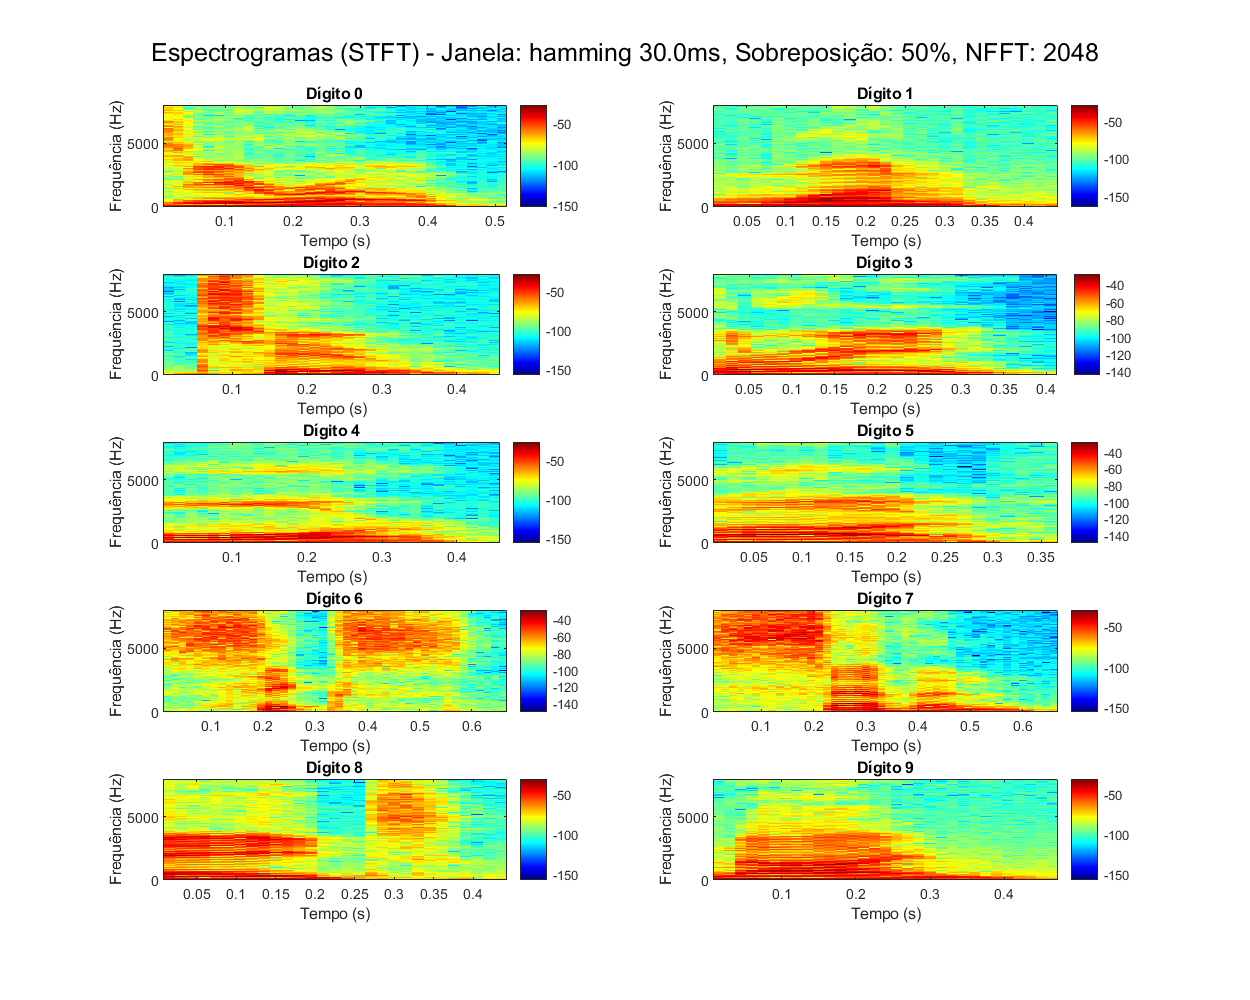

% ===== Exercício 22: Calcular e Visualizar STFT (Modificado para remover silêncio final) =====
digitosUnicos = unique(tabelaAudio.Digito);
numDigitos = length(digitosUnicos);

figure('Name', 'STFT por Dígito (Exemplos)', 'Position', [50, 50, 1000, 800]);

tamanhoJanelaSegundos = 0.03;
percentagemSobreposicao = 50;

for i = 1:numDigitos
    digitoAtual = digitosUnicos(i);

    idxPrimeiroExemplo = find(tabelaAudio.Digito == digitoAtual, 1, 'first');

    if isempty(idxPrimeiroExemplo)
        warning('Não foram encontrados exemplos para o dígito %d.', digitoAtual);
        continue;
    end

    sinal = tabelaAudio.SinalPreProcessado{idxPrimeiroExemplo};
    Fs = tabelaAudio.TaxaAmostragem(idxPrimeiroExemplo);
    
    lastNonZero = find(sinal ~= 0, 1, 'last');
    if ~isempty(lastNonZero) && lastNonZero < length(sinal)
        sinal = sinal(1:lastNonZero);
    end

    tamanhoJanelaAmostras = round(tamanhoJanelaSegundos * Fs);
    numAmostrasSobreposicao = round(tamanhoJanelaAmostras * percentagemSobreposicao / 100);

    janela = hamming(tamanhoJanelaAmostras);

    nfft = max(256, 2^nextpow2(tamanhoJanelaAmostras));

    [S, F, T, P] = spectrogram(sinal, janela, numAmostrasSobreposicao, nfft, Fs, 'yaxis');


    subplot(5, 2, i);
    imagesc(T, F, 10*log10(P)); 
    axis xy;
    ylim([0 8000]); 
    xlabel('Tempo (s)');
    ylabel('Frequência (Hz)');
    title(sprintf('Dígito %d', digitoAtual));
    colorbar;
    colormap('jet');

end

sgtitle(sprintf('Espectrogramas (STFT) - Janela: %s %.1fms, Sobreposição: %d%%, NFFT: %d', ...
    func2str(@hamming), tamanhoJanelaSegundos*1000, percentagemSobreposicao, nfft));

**Exercício 23**

**Escolha das caracteristicas:**

 **TF_StdSpecCentroid (Desvio-padrão do Centróide Espectral)**

Mede a variação temporal do “centro de massa” do espectro. Valores altos indicam deslocamentos frequentes entre graves e agudos (útil para dígitos com transições rápidas, p.ex. consoantes plosivas), enquanto valores baixos caracterizam sinais mais estáveis (vogais prolongadas).

**TF_MeanSpecRolloff (Roll-off Espectral Médio, 85 %)**

Frequência abaixo da qual se acumula 85 % da energia média do espectro. Dígitos com predominância de componentes graves exibem roll-off baixo; aqueles com mais energia em agudos, roll-off alto. Bom discriminador de timbre global.

**TF_MeanLowFreqEnergy (Energia Média em ≤ 1 kHz)**

Soma da energia espectral até 1 kHz, média ao longo do tempo. Vogais e formantes concentram energia em baixas frequências; plosivas e fricativas, em frequências mais altas. Realça diferenças entre dígitos dominados por vogais versus consoantes.

**TF_MeanSpecSkewness (Assimetria Espectral Média)**

Terceiro momento normalizado do espectro: quantifica se a energia tende a “cauda” em agudos (skewness positiva) ou em graves (negativa). Facilita identificar dígitos cujas vogais ou consoantes introduzem enviesamentos espectrais distintos.

**TF_MeanSpecSpread (Largura Espectral Média)**

Raiz-quadrada da variância espectral média: indica dispersão da energia em torno do centróide. Spread elevado reflete espectros complexos (fricativas/plosivas); spread baixo corresponde a espectros concentrados (vogais puras). Ideal para capturar “complexidade” do som.

% ===== Exercício 23: Extrair as 5 Melhores Características Tempo-Frequência (STFT) =====

numSinais = height(tabelaAudio);

nomesFeaturesTF_Melhores = {'TF_StdSpecCentroid', 'TF_MeanSpecRolloff', 'TF_MeanLowFreqEnergy', ...
                            'TF_MeanSpecSkewness', 'TF_MeanSpecSpread'};

for k = 1:length(nomesFeaturesTF_Melhores)
    tabelaAudio.(nomesFeaturesTF_Melhores{k}) = NaN(numSinais, 1);
end

epsilon = 1e-10; % Pequeno valor para estabilidade numérica (evitar log(0) ou divisão por zero)

% --- Definição das variáveis freqLimiteBaixa e percentilRolloff ---
freqLimiteBaixa = 1000;
percentilRolloff = 0.85;


for i = 1:numSinais
    sinal = tabelaAudio.SinalPreProcessado{i};
    Fs = tabelaAudio.TaxaAmostragem(i);

    lastNonZero = find(sinal ~= 0, 1, 'last');
    if ~isempty(lastNonZero) && lastNonZero < length(sinal)
        sinal = sinal(1:lastNonZero);
    end

    tamanhoJanelaAmostras = round(tamanhoJanelaSegundos * Fs);
    if length(sinal) == 0 || tamanhoJanelaAmostras == 0 || length(sinal) < tamanhoJanelaAmostras
        warning('Sinal %d muito curto (%d amostras) após remoção de silêncio para a janela definida (%d amostras). Saltando características TF.', i, length(sinal), tamanhoJanelaAmostras);
         for k = 1:length(nomesFeaturesTF_Melhores)
             tabelaAudio.(nomesFeaturesTF_Melhores{k})(i) = 0;
         end
        continue; 
    end

    numAmostrasSobreposicao = round(tamanhoJanelaAmostras * percentagemSobreposicao / 100);
    janela = hamming(tamanhoJanelaAmostras);
    nfft = max(256, 2^nextpow2(tamanhoJanelaAmostras)); 

    [~, F, T, P] = spectrogram(sinal, janela, numAmostrasSobreposicao, nfft, Fs, 'yaxis');

    if isempty(P) || isempty(F) || isempty(T)
        warning('Espectrograma vazio para o sinal %d. Saltando características TF.', i);
         for k = 1:length(nomesFeaturesTF_Melhores)
             tabelaAudio.(nomesFeaturesTF_Melhores{k})(i) = 0;
         end
    else
        numFrames = size(P, 2);
        specCentroidFrame = zeros(1, numFrames); 
        specRolloffFrame  = zeros(1, numFrames); 
        lowFreqEnergyFrame= zeros(1, numFrames);
        specSpreadFrame   = zeros(1, numFrames);
        specSkewnessFrame = zeros(1, numFrames); 

        idxFreqBaixa = find(F <= freqLimiteBaixa);

        for t = 1:numFrames
            frameAtual = P(:, t);
            energiaTotalFrame = sum(frameAtual);

            if energiaTotalFrame > epsilon

                specCentroidFrame(t) = sum(F .* frameAtual) / energiaTotalFrame;

                energiaCumulativa = cumsum(frameAtual);
                idxRolloff = find(energiaCumulativa >= percentilRolloff * energiaTotalFrame, 1, 'first');
                 if ~isempty(idxRolloff)
                     specRolloffFrame(t) = F(idxRolloff);
                 else
                     specRolloffFrame(t) = F(end);
                 end

                 if ~isempty(idxFreqBaixa)
                     lowFreqEnergyFrame(t) = sum(frameAtual(idxFreqBaixa));
                 else
                     lowFreqEnergyFrame(t) = 0;
                 end

                 weighted_variance = sum((F - specCentroidFrame(t)).^2 .* frameAtual) / energiaTotalFrame;
                 specSpreadFrame(t) = sqrt(weighted_variance);

                 weighted_third_moment = sum((F - specCentroidFrame(t)).^3 .* frameAtual) / energiaTotalFrame;
                 if specSpreadFrame(t) > epsilon 
                     specSkewnessFrame(t) = weighted_third_moment / (specSpreadFrame(t)^3 + epsilon);
                 else
                     specSkewnessFrame(t) = 0;
                 end

            else
                specCentroidFrame(t) = 0;
                specRolloffFrame(t) = 0;
                lowFreqEnergyFrame(t) = 0;
                specSpreadFrame(t) = 0;
                specSkewnessFrame(t) = 0;
            end

        end 

        tabelaAudio.TF_StdSpecCentroid(i)  = std(specCentroidFrame, 0, 'omitnan');
        tabelaAudio.TF_MeanSpecRolloff(i)  = mean(specRolloffFrame, 'omitnan');
        tabelaAudio.TF_MeanLowFreqEnergy(i)=mean(lowFreqEnergyFrame, 'omitnan');
        tabelaAudio.TF_MeanSpecSkewness(i) = mean(specSkewnessFrame, 'omitnan');
        tabelaAudio.TF_MeanSpecSpread(i)   = mean(specSpreadFrame, 'omitnan');


         if isnan(tabelaAudio.TF_StdSpecCentroid(i)),  tabelaAudio.TF_StdSpecCentroid(i) = 0; end
         if isnan(tabelaAudio.TF_MeanSpecRolloff(i)),  tabelaAudio.TF_MeanSpecRolloff(i) = 0; end
         if isnan(tabelaAudio.TF_MeanLowFreqEnergy(i)), tabelaAudio.TF_MeanLowFreqEnergy(i) = 0; end
         if isnan(tabelaAudio.TF_MeanSpecSkewness(i)), tabelaAudio.TF_MeanSpecSkewness(i) = 0; end
         if isnan(tabelaAudio.TF_MeanSpecSpread(i)),   tabelaAudio.TF_MeanSpecSpread(i) = 0; end

    end

end

Extração das 5 Melhores Características Tempo-Frequência (STFT) concluída.



disp('Primeiras linhas da tabela com as 5 melhores características TF:');

Primeiras linhas da tabela com as 5 melhores características TF:


disp(head(tabelaAudio(:, [{'Digito'}, nomesFeaturesTF_Melhores])));

    Digito    TF_StdSpecCentroid    TF_MeanSpecRolloff    TF_MeanLowFreqEnergy    TF_MeanSpecSkewness    TF_MeanSpecSpread
    ______    __________________    __________________    ____________________    ___________________    _________________

      0             398.62                680.38                0.0018813               26.957                492.85      
      0             354.34                503.13                0.0032983               24.427                544.98      
      0             421.48                  1256               0.00092386               15.165                752.84      
      0               1416                  1248                0.0011922               12.784                738.55      
      0             980.69                1147.7         

**Exercício 24**

**Característica escolhidas**

Pelos boxplots e dispersão 3D, parecem ser as melhores:

- **TF_StdSpecCentroid** (grande separação em desvios do centróide).

- **TF_MeanLowFreqEnergy** (vários dígitos têm energia de graves distinta).

- **TF_MeanSpecSkewness** (assimetria traz diferenciação adicional).

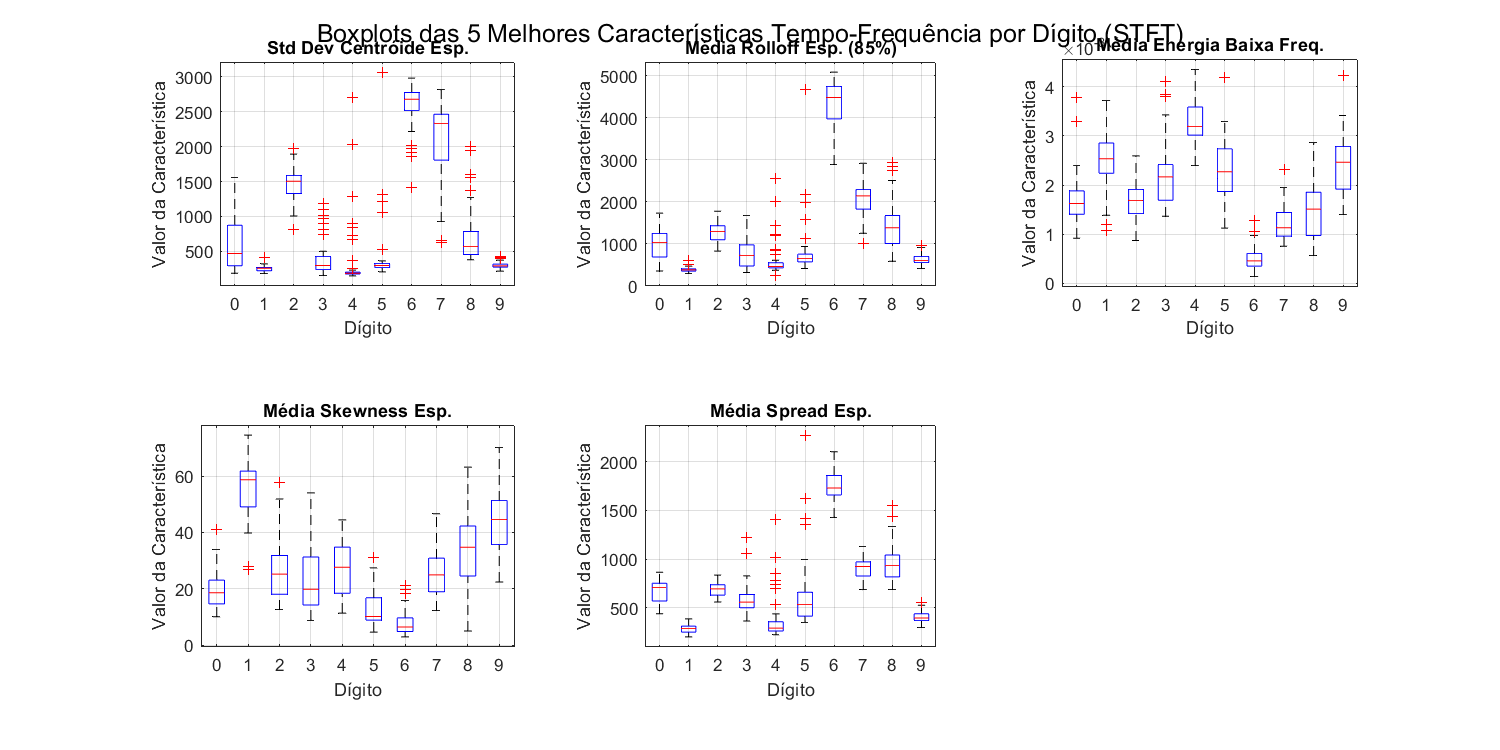

% ===== Exercício 24: Análise e Visualização das 5 Melhores Características TF =====

titulosBoxplotsTF_Melhores = {'Std Dev Centróide Esp.', 'Média Rolloff Esp. (85%)', 'Média Energia Baixa Freq.', ...
                              'Média Skewness Esp.', 'Média Spread Esp.'};


figure('Name', 'Boxplots - 5 Melhores Características TF (STFT)', 'Position', [100 100 1200 600]);
numPlotsTF = length(nomesFeaturesTF_Melhores);

rowsTF = 2;
colsTF = 3;

for k = 1:numPlotsTF
    subplot(rowsTF, colsTF, k);
     if ismember(nomesFeaturesTF_Melhores{k}, tabelaAudio.Properties.VariableNames)
         boxplot(tabelaAudio.(nomesFeaturesTF_Melhores{k}), tabelaAudio.Digito, 'Whisker', 1.5);
         title(titulosBoxplotsTF_Melhores{k});
         xlabel('Dígito');
         ylabel('Valor da Característica');
         grid on;

     else
         warning('Característica TF "%s" não encontrada na tabela. Pulando boxplot.', nomesFeaturesTF_Melhores{k});
     end
end
sgtitle('Boxplots das 5 Melhores Características Tempo-Frequência por Dígito (STFT)');

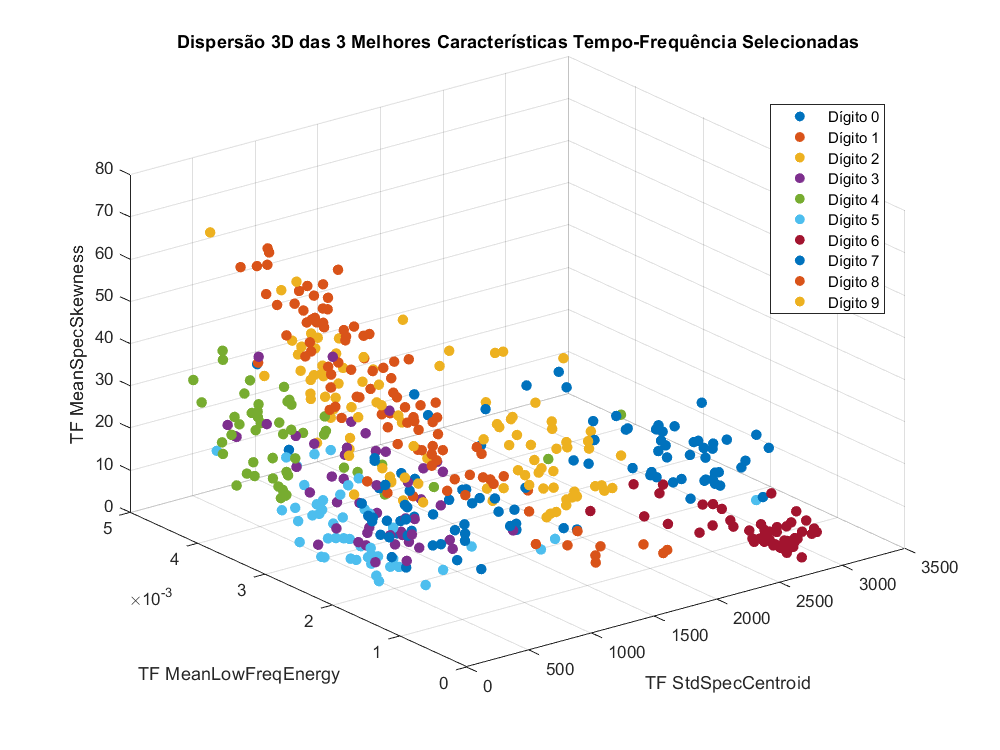

featureX_3D = 'TF_StdSpecCentroid';
featureY_3D = 'TF_MeanLowFreqEnergy';
featureZ_3D = 'TF_MeanSpecSkewness';


figure('Name', 'Gráfico 3D - 3 Melhores Características TF Selecionadas', 'Position', [200 200 800 600]);
hold on;
cores = lines(numDigitos);

if ismember(featureX_3D, tabelaAudio.Properties.VariableNames) && ...
   ismember(featureY_3D, tabelaAudio.Properties.VariableNames) && ...
   ismember(featureZ_3D, tabelaAudio.Properties.VariableNames)

    for i = 1:numDigitos
        d = digitosUnicos(i);
        idx = (tabelaAudio.Digito == d);
        scatter3(tabelaAudio.(featureX_3D)(idx), tabelaAudio.(featureY_3D)(idx), tabelaAudio.(featureZ_3D)(idx), ...
               40, cores(i,:), 'filled', 'DisplayName', sprintf('Dígito %d', d));
    end

    xlabel(strrep(featureX_3D, '_', ' '));
    ylabel(strrep(featureY_3D, '_', ' '));
    zlabel(strrep(featureZ_3D, '_', ' '));
    title('Dispersão 3D das 3 Melhores Características Tempo-Frequência Selecionadas');
    grid on; legend('Location', 'best'); view(3); rotate3d on;

else
    warning('Uma ou mais das características 3D selecionadas ("%s", "%s", "%s") não existem na tabela. Não foi possível gerar o gráfico 3D.', featureX_3D, featureY_3D, featureZ_3D);
end

hold off;

disp(nomesFeaturesTF_Melhores');

    {'TF_StdSpecCentroid'  }
    {'TF_MeanSpecRolloff'  }
    {'TF_MeanLowFreqEnergy'}
    {'TF_MeanSpecSkewness' }
    {'TF_MeanSpecSpread'   }



**Exercício 25**

**Comparação STFT vs DWT**

- **STFT** fornece características tempo-frequência **localizadas** em janelas fixas: detalha evolução espectral sobre o tempo, mas com trade-offs fixos resolução temporal vs frequência.

- **DWT** decompõe o sinal em bandas de frequência com **resolução multiescala**: melhor resolução temporal em altas frequências (níveis inferiores) e melhor resolução em frequência em baixas frequências (níveis superiores).

- Em termos de discriminabilidade:

- A **DWT** concentra energia em coeficientes de detalhe que capturam transientes (ataques plosivos de consoantes), potencialmente muito úteis para dígitos com sons plosivos (“two”, “five”).

- A **STFT** extrai momentos espectrais (centroid, rolloff) que capturam forma geral do espectro das vogais, mais robustas a ruído estático.

- **Conclusão**: usar em combinação ambas as abordagens pode aumentar a separabilidade, pois cada uma capta aspetos complementares do sinal.

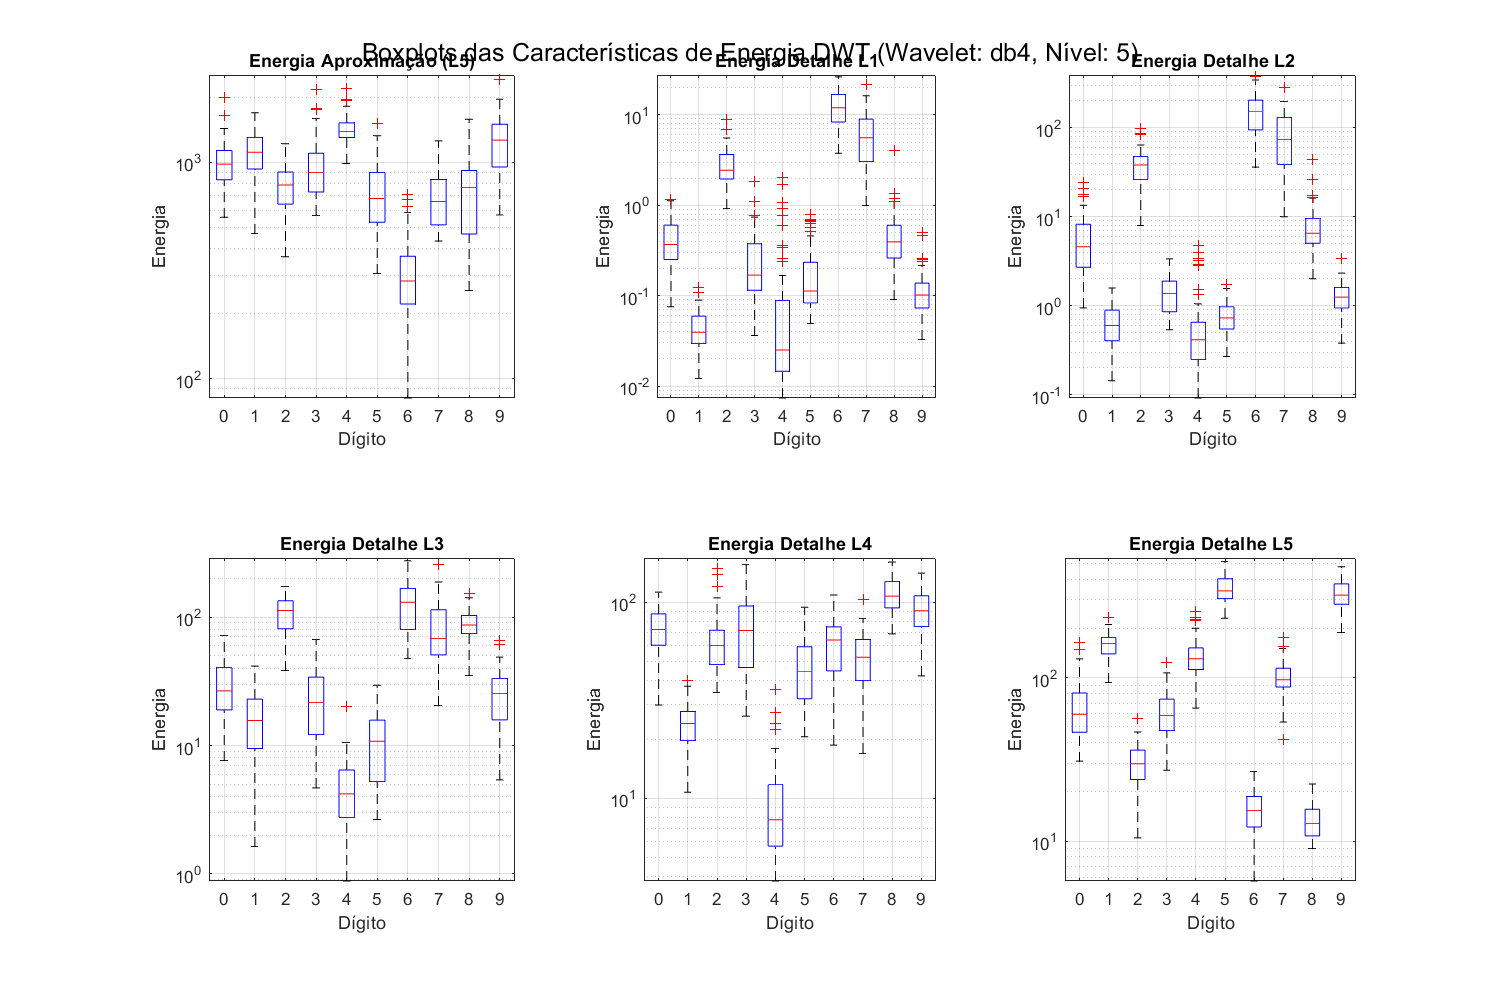

% ===== Exercício 25: Aplicar DWT, Extrair Características de Energia e Visualizar =====
nomeWavelet = 'db4';
nivelDecomposicao = 5; 

minLen = min(cellfun(@(s) length(s(~s==0)), tabelaAudio.SinalPreProcessado));
maxLevel = wmaxlev(minLen, nomeWavelet);
if nivelDecomposicao > maxLevel
    nivelDecomposicao = maxLevel;
    fprintf('Nível de decomposição ajustado para %d devido ao comprimento mínimo do sinal (%d amostras não zero).\n', nivelDecomposicao, minLen);
end

numFeaturesDWT = nivelDecomposicao + 1;
nomesFeaturesDWT = cell(1, numFeaturesDWT);
titulosBoxplotsDWT = cell(1, numFeaturesDWT);

nomesFeaturesDWT{1} = 'DWT_Energy_App';
titulosBoxplotsDWT{1} = sprintf('Energia Aproximação (L%d)', nivelDecomposicao);

for lvl = 1:nivelDecomposicao
    nomesFeaturesDWT{lvl+1} = sprintf('DWT_Energy_Det_L%d', lvl);
    titulosBoxplotsDWT{lvl+1} = sprintf('Energia Detalhe L%d', lvl);
end

hasDWTCols = all(ismember(nomesFeaturesDWT, tabelaAudio.Properties.VariableNames));

if ~hasDWTCols
    for k = 1:numFeaturesDWT
        tabelaAudio.(nomesFeaturesDWT{k}) = NaN(numSinais, 1);
    end
end


for i = 1:numSinais
    sinal = tabelaAudio.SinalPreProcessado{i};

    lastNonZero = find(sinal ~= 0, 1, 'last');
    if ~isempty(lastNonZero) && lastNonZero < length(sinal)
        sinalDWT = sinal(1:lastNonZero);
    else
        sinalDWT = sinal;
    end
   

    if length(sinalDWT) < 2^nivelDecomposicao
          warning('Sinal %d muito curto (%d amostras não zero) para o nível %d de decomposição DWT com %s (requer pelo menos %d amostras). Saltando DWT.', i, length(sinalDWT), nivelDecomposicao, nomeWavelet, 2^nivelDecomposicao);
            tabelaAudio.DWT_Energy_App(i) = 0;
            for lvl = 1:nivelDecomposicao
                 tabelaAudio.(sprintf('DWT_Energy_Det_L%d', lvl))(i) = 0;
            end
          continue;
    end

    % Aplicar a DWT
    [C, L] = wavedec(sinalDWT, nivelDecomposicao, nomeWavelet);

    cA = appcoef(C, L, nomeWavelet, nivelDecomposicao);
    tabelaAudio.DWT_Energy_App(i) = sum(cA.^2);

    for lvl = 1:nivelDecomposicao
        cD = detcoef(C, L, lvl);
        tabelaAudio.(sprintf('DWT_Energy_Det_L%d', lvl))(i) = sum(cD.^2);
    end

    % Tratamento de NaNs para características DWT
    if isnan(tabelaAudio.DWT_Energy_App(i)), tabelaAudio.DWT_Energy_App(i) = 0; end
    for lvl = 1:nivelDecomposicao
       if isnan(tabelaAudio.(sprintf('DWT_Energy_Det_L%d', lvl))(i))
            tabelaAudio.(sprintf('DWT_Energy_Det_L%d', lvl))(i) = 0;
       end
    end
end

if numFeaturesDWT > 0 && all(ismember(nomesFeaturesDWT, tabelaAudio.Properties.VariableNames))
    figure('Name', 'Boxplots - Características de Energia (DWT)', 'Position', [150 150 1200 800]); % Ajustar tamanho da figura
    numPlotsDWT = numFeaturesDWT;
    rowsDWT = floor(sqrt(numPlotsDWT));
    colsDWT = ceil(numPlotsDWT / rowsDWT);
    if colsDWT > 6 % Limitar número de colunas para melhor visualização
         colsDWT = 6;
         rowsDWT = ceil(numPlotsDWT / colsDWT);
    end


    for k = 1:numPlotsDWT
        subplot(rowsDWT, colsDWT, k);
         if ismember(nomesFeaturesDWT{k}, tabelaAudio.Properties.VariableNames)
             boxplot(tabelaAudio.(nomesFeaturesDWT{k}), tabelaAudio.Digito, 'Whisker', 1.5);
             title(titulosBoxplotsDWT{k});
             xlabel('Dígito');
             ylabel('Energia');
             grid on;
             set(gca, 'YScale', 'log');
         else
             warning('Característica DWT "%s" não encontrada na tabela durante a plotagem. Pulando boxplot.', nomesFeaturesDWT{k});
         end
    end
    sgtitle(sprintf('Boxplots das Características de Energia DWT (Wavelet: %s, Nível: %d)', nomeWavelet, nivelDecomposicao));
else
     fprintf('Não há características DWT para gerar boxplots (verifique a extração).\n');
end

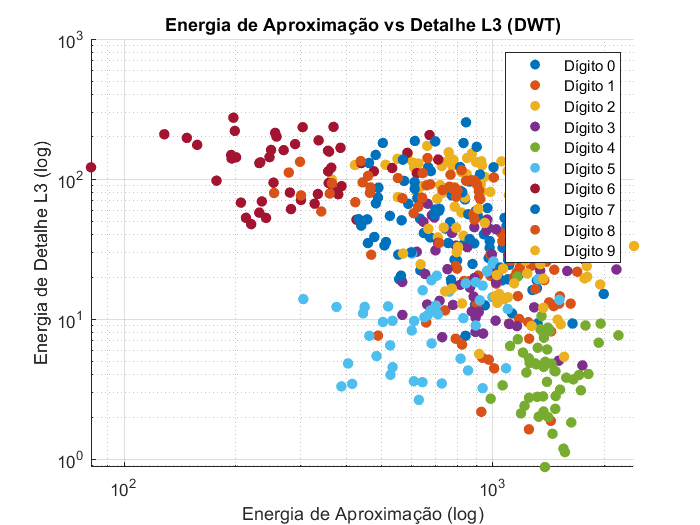


% === Gráfico 2D: Energia de Aproximação vs Energia de Detalhe (L3) ===
melhorNivel = 3;
nomeDet = sprintf('DWT_Energy_Det_L%d', melhorNivel);

figure;
hold on;
cores = lines(numDigitos);
for i = 1:numDigitos
    d = digitosUnicos(i);
    idx = (tabelaAudio.Digito == d);
    scatter(tabelaAudio.DWT_Energy_App(idx), tabelaAudio.(nomeDet)(idx), 40, cores(i,:), 'filled', 'DisplayName', sprintf('Dígito %d', d));
end
set(gca, 'XScale', 'log', 'YScale', 'log');
xlabel('Energia de Aproximação (log)');
ylabel('Energia de Detalhe L3 (log)');
title('Energia de Aproximação vs Detalhe L3 (DWT)');
legend('show');
grid on;
hold off;

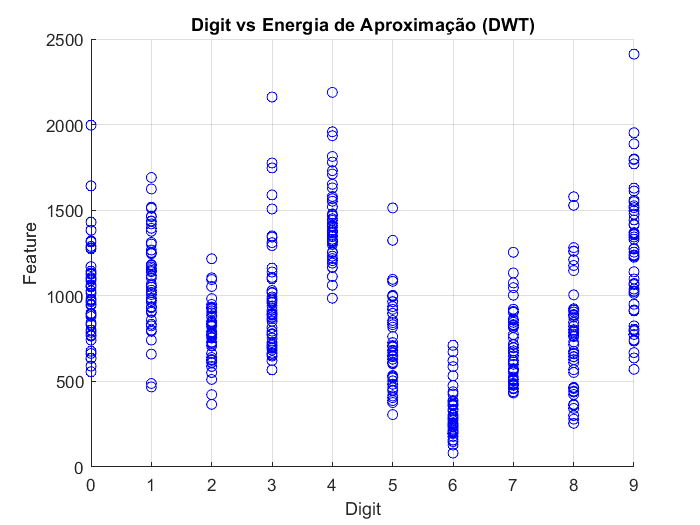


% === Gráfico 2D: Dígito vs Energia de Aproximação (scatter, igual à imagem) ===
figure;
scatter(tabelaAudio.Digito, tabelaAudio.DWT_Energy_App, 'o', 'MarkerEdgeColor', 'b');
xlabel('Digit');
ylabel('Feature');
title('Digit vs Energia de Aproximação (DWT)');
grid on;

**Exercício 26**

Guardar a informação na tabela

% ===== Exercício 26: Atualizar o ficheiro .mat =====
save(caminhoTabela, 'tabelaAudio');
fprintf('Arquivo "%s" atualizado com sucesso com as 5 melhores características TF e DWT!\n', caminhoTabela);

Arquivo "C:\Users\gamer\OneDrive\Documentos\MATLAB\projeto\resultados\tabelaAudio.mat" atualizado com sucesso com as 5 melhores características TF e DWT!
